# Solve Systems of Linear Equations with Jacobi Method

For large-scale numerical problems, iterative methods can be more effective than direct methods, altough the choice between a direct method and an iterative one depends on several factors, like the structure and sparsity of the coefficient matrix. This example shows how to solve a system of linear equations of the form $A\mathbf{x} = \mathbf{b}$ using the Jacobi method; it also presents an alternative approach to solve the system efficiently, using distributed arrays to leverage parallel computing..

Direct methods in [`mldivide`](https://it.mathworks.com/help/matlab/ref/double.mldivide.html) support the parallel solution of distributed linear systems but may not be very efficient for certain large and sparse systems. Iterative methods compute a series of solutions from an initial guess, converging to a final result after several iterations. These iterations can be less computationally demanding than working out the exact solution with direct methods. Generally speaking, iterative methods are most effective when used along with sparse matrices, but they can also be successfully employed with dense data.

Distributed arrays distribute data, including full and sparse matrices, from your client workspace to a parallel pool in your local machine or on a cluster. Each worker stores a portion of the array in its memory, but can also communicate with the other workers to access all elements of the array as they need them.

## Introduction

The coefficient matrix $A = (a_{ij})\in\mathbb{R}^{n\times n}$ of the linear system $A\mathbf{x}=\mathbf{b}$ is the sparse block tridiagonal matrix resulting from the discretization of the Poisson's equation, defined on the domain $\Omega=[0, 1]\times[0, 1]$, with the finite-difference method. The order of this square matrix, dependent on the parameter $m \geq1$, is $n = m^2$. By definition, $A$ is a strict diagonally dominant matrix, which is a sufficient condition for the convergence of the Jacobi method.

clc
clear
m = 10;
n = m^2;
A = gallery('poisson', m);
fprintf(['Size of coefficient matrix A: '...
         '%u x %u \n\n'],n,n);

Size of coefficient matrix A: 100 x 100 



The right hand vector $\mathbf{b}\in\mathbb{R}^{n}$ is defined as


$$b = \sum_ {A_{i} \in J} A_{i}$$


where $J = \{A_{1}, A_{2}, ..., A_{N}\}$represents the set of the columns of $A$, leading to an exact solution to $A\mathbf{x} = \mathbf{b}$ of the form $\mathbf{x} = (1,1,...,1)^T$. This provides a simple way to verify the accuracy of the computed result.

b = sum(A,2);
x = ones(n,1);

## Solve your System of Linear Equations with the Jacobi Method

The `jacobi` function from the Jacobi Method Toolbox contains an implementation of the Jacobi method, an iterative method for the solution of systems of linear equations which iteratively generates a series of approximate solutions for $\mathbf{x}$.

The stopping criteria for the method depends on two input arguments: `maxit`, the maximum number of iteration steps and `tol`, the maximum tolerance. For both distributed and on-client arrays, `jacobi` uses the same default configuration:

- The default maximum tolerance, `tol, `is ${10}^{-6}$.

- The default maximum number of iteration steps, `maxit`, is 100.

[xJM1,flagJM1,relresJM1,iterJM1,resvecJM1] = jacobi(A,b);

When the system is solved, you can check the absolute error $\|\mathbf{e}^{(k)}\|$ between each component of the approximate result `xJM1` and the exact solution `x`. In this first attempt, the error is relatively high.

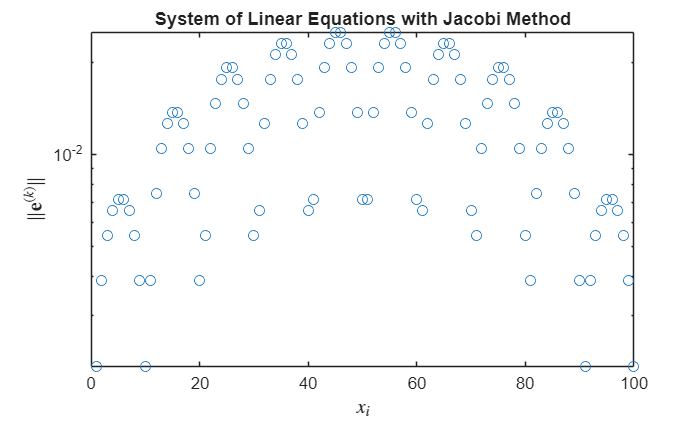

errJM1 = abs(x - xJM1);

figure(1)
hold off
semilogy(errJM1, 'o');
title('System of Linear Equations with Jacobi Method');
ylabel('$\|\mathbf{e}^{(k)}\|$', 'Interpreter','latex','FontSize',12);
xlabel('$x_{i}$', 'Interpreter','latex','FontSize',12);

According to its prototype, `jacobi` returns several output arguments, including

- `x:` the approximate solution for the system;

- `flag`: a convergence flag representing the final execution state of the method. For example, a value of `0` indicates the solution has properly converged.

- `resvec`: an array whose elements corresponds to the relative residual at the end of each iteration. This is a measure of the accuracy of the solution computed between two contiguous steps.

fprintf(['jacobi stopped at iteration %u without ' ...
        'converging to the desired tolerance %0.2g ' ...
        'because the maximum number of\niterations ' ...
        'was reached.\nThe iterate returned has ' ...
        'relative residual %0.2g.\n'], ...
        iterJM1, 1e-6, relresJM1);

jacobi stopped at iteration 100 without converging to the desired tolerance 1e-06 because the maximum number of
iterations was reached.
The iterate returned has relative residual 0.0033.


In this example, the solution does not converge within the default maximum number of iterations, resulting in the high error.

To increase the likelihood of convergence, you can adjust the maximum number of iteration steps.

maxit = 3e5;

tJM2 = tic;
[xJM2,flagJM2,relresJM2,iterJM2,resvecJM2] = jacobi(A,b,[],maxit);
tJM2 = toc(tJM2);

fprintf(['jacobi converged at iteration %u to a ' ...
        'solution with relative residual %0.2g.\n'],iterJM2,relresJM2);

jacobi converged at iteration 296 to a solution with relative residual 9.9e-07.


With the custom settings, the method converges and the absolute error exhibits a sharp decrease compared to the previous attempt.

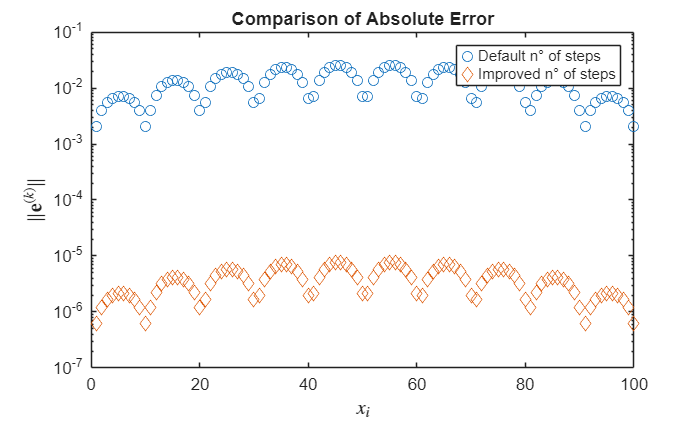

errJM2 = abs(x - xJM2);

figure(2)
semilogy(errJM1,'o');
hold on
semilogy(errJM2,'diamond');
title('Comparison of Absolute Error');
ylabel('$\|\mathbf{e}^{(k)}\|$', 'Interpreter','latex','FontSize',12);
xlabel('$x_{i}$', 'Interpreter','latex','FontSize',12);
legend('Default n° of steps','Improved n° of steps');
hold off

The `jacobi` method returns `resvec`, the vector of the residual norm at each iteration step; the evolution of the residuals during the execution can help you understand why the algorithm did not reached an acceptable solution.

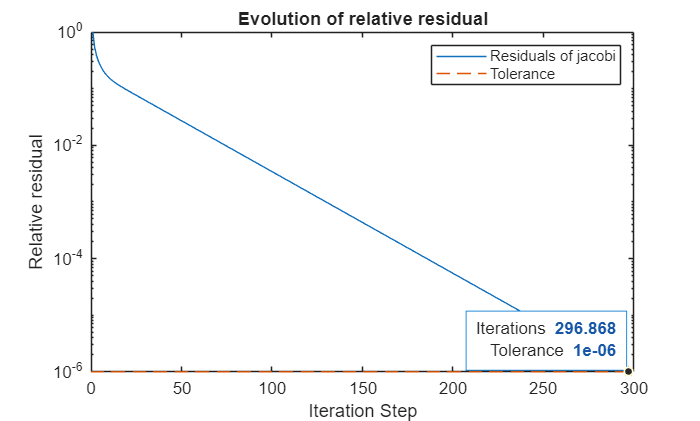

relresvecJM = resvecJM2./resvecJM2(1);
tol = 1e-6;

idx1 = find(relresvecJM > tol, 1, 'last');
idx2 = idx1 + 1;

p1 = [idx1, relresvecJM(idx1)];
p2 = [idx2, relresvecJM(idx2)]; 

px = p1(1) + (tol - p1(2)) * (p2(1) - p1(1)) / (p2(2) - p1(2));
py = tol; 

figure(3)
f=semilogy(relresvecJM);
hold on
semilogy(f.Parent.XLim,[tol, tol],'--')
p = plot(px, py, 'p');

dt = datatip(p);
p.DataTipTemplate.DataTipRows(1).Label = "Iterations";
p.DataTipTemplate.DataTipRows(2).Label = "Tolerance"; 
dt.Visible = 'on';

title("Evolution of relative residual");
ylabel('Relative residual');
xlabel("Iteration Step");
legend('Residuals of jacobi','Tolerance')
hold off

It is straightforward pointing out that the default number of iterations is not enough to achieve a good solution for this system.

## Solve your System of Linear Equations with the Jacobi Method using Distributed Arrays

The definition of the input data for the problem is analogous to the previous scenario, but the construction of distributed arrays through [`distributed`](https://it.mathworks.com/help/releases/R2025a/parallel-computing/distributed.html?searchPort=4562#br67dtg-1)`. `When you use the [`distributed`](https://it.mathworks.com/help/releases/R2025a/parallel-computing/distributed.html?searchPort=4562#br67dtg-1) function, MATLAB automatically starts a parallel pool using your default parallel environment. 

Since `sum` acts on a distributed array, `b` is also distributed and its data is stored on the memory of the workers of your parallel pool.

A = distributed(gallery('poisson', m));

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.


b = sum(A,2);

The MATLAB scheduler is responsible for selecting the appropriate source code at runtime, depending on the data types of the arguments passed to the `jacobi` function.

tJM3 = tic;
[xJM3,flagJM3,relresJM3,iterJM3,resvecJM3] = jacobi(A,b,[],maxit);
tJM3 = toc(tJM3);
fprintf(['jacobi converged at iteration %u to a ' ...
        'solution with relative residual %0.2g.\n'],iterJM3,relresJM3);

jacobi converged at iteration 296 to a solution with relative residual 9.9e-07.


The use of distributed arrays to split data among the workers allows to solve massively large systems of linear equations, whose coefficient matrix does not entirely fit in the memory of a single computer. 

Note that the execution time for the distributed version might not be faster on a local machine, especially for problems of this size. The data transfer overhead can outweigh the benefits of parallelization. This is also reflected in the execution times.

fprintf([...
    '\nTime to solve system with Jacobi Method:                        %d s', ...
    '\nTime to solve system with Jacobi Method and distributed arrays: %d s'],tJM2,tJM3);


Time to solve system with Jacobi Method:                        2.633100e-03 s
Time to solve system with Jacobi Method and distributed arrays: 5.840073e+00 s

At the end of computations, you can delete your parallel pool. The [`gcp`](https://it.mathworks.com/help/releases/R2025a/parallel-computing/gcp.html) function returns the current parallel pool object so you can delete the current pool.

delete(gcp('nocreate'))

Parallel pool using the 'Processes' profile is shutting down.


The Jacobi method is an algorithm with low computational intensity, meaning it performs a relatively low number of floating-point operations for each byte of data moved between the workers. Therefore, for large-scale problems, a solver with a higher rate of convergence, such as the preconditioned conjugate gradient method, is preferred, whereas the Jacobi method is used as a preconditioner to improve the efficiency of the solution.

*2025 - Thomas Fabbris*